close all, clear all clc
% number of samples of each cluster
K = 100;
% offset of clusters
q = .6;
% define 2 groups of input data
A1 = [rand(1,K)-q; rand(1,K)+q]; B1 = [rand(1,K)+q; rand(1,K)+q]; C1 = [rand(1,K)+q; rand(1,K)-q]; D1 = [rand(1,K)-q; rand(1,K)-q]; A = [A1 C1];
B = [B1 D1];
% plot data
plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
grid on
hold on
% Define output coding
% coding (+1/0) for 2-class XOR problem
a = 0; b = 1;
% Prepare inputs and outputs for network training
% define inputs (combine samples from all two classes)
P = [A B];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B))];
% create a neural network
net = feedforwardnet([20]);
% adjust the network for classification
for i =1:(length(net.layers)-1)
    %net.layers{i}.transferFcn = 'logsig'; % you can use either logsig or tansig
    net.layers{i}.transferFcn = 'tansig';
end
net.layers{end}.transferFcn = 'softmax';
% Cost function: crossentropy
net.performFcn = 'crossentropy';
% Train function: Gradient descent with momentum
net.trainFcn = 'traingdm'; net.trainParam.lr = 0.5; net.trainParam.mc = 0.8; net.trainParam.epochs = 2000;
% Train function: Scaled Conjugate Gradients. You can tried it instead of traingdm.
  
%net.trainFcn = 'trainscg'; net.trainParam.lr = 0.1; net.trainParam.mc = 0.8; %net.trainParam.epochs = 1000;
% The processFcns parameter is used when you want to perform certain preprocessing % steps on the network inputs and targets. Be careful, Matlab perform the most common % preprocessings automatically when you create a network. If you do not want any
% preprocessing you need to disable this parameter.
net.outputs{end}.processFcns = {};
% train the neural network
[net,tr,Y,E] = train(net,P,T);
% Notice that tr has the indices of the training, validation and test data sets: % tr.trainInd
% tr.valInd
% tr.testInd
% show network
view(net);
% Accuracy
fprintf('Accuracy: %f\n',100-100*sum(abs((Y>0.5)-T))/length(T))

Accuracy: 100.000000


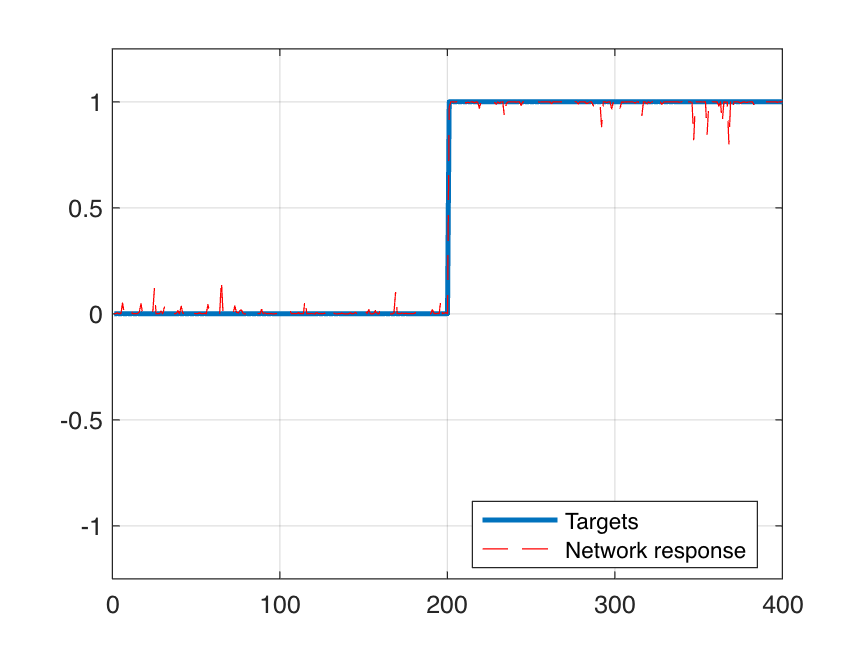

% Plot targets and network response to see how good the network learns the data
figure(2)
plot(T','linewidth',2)
hold on
plot(Y','r--')
grid on
legend('Targets','Network response','location','best')
ylim([-1.25 1.25]);

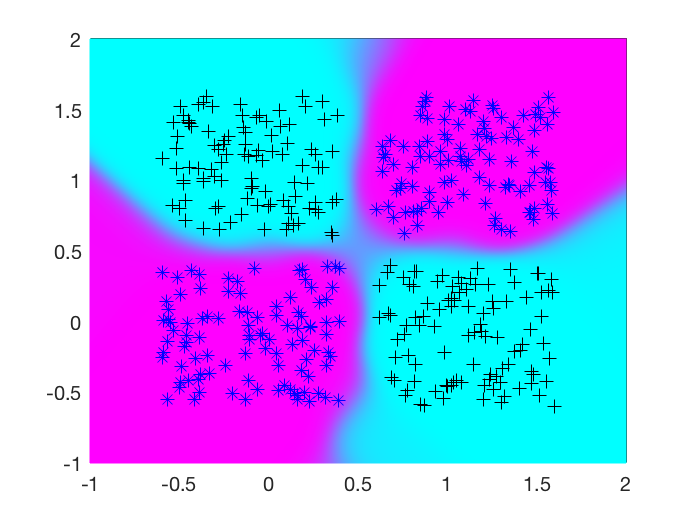

% Plot classification result for the complete input space (separation by hyperplanes)
% generate a grid
span = -1:.005:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';
% simulate neural network on a grid
aa = net(pp);
% plot classification regions
figure(1);
mesh(P1,P2,reshape(aa,length(span),length(span))-5);
colormap cool
view(2);